format shortG
u = symunit;
% separateUnits(x)
% unitConvert(expr,units)

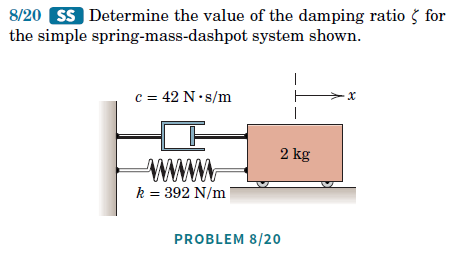

Vi kontroller først hvilken form for dæmpning vi har 

clear 

disp('Vi opstiller vores data')

Vi opstiller vores data


k = 392 % N/m    %* u.N / u.m

k =    392


m = 2 % kg      %* u.kg

m =      2


c = 42 %N*s/m   %* u.N * u.s / u.m

c =     42


disp('Egensvingningen findes')

Egensvingningen findes


w_n = sqrt(k/m) %egensvingningen

w_n =     14



disp('Dæmpningsrationen findes')

Dæmpningsrationen findes


zeta = c/(2 * m * w_n) % viscous damping factor or damping ratio

zeta =          0.75



if separateUnits(zeta) < 1
    disp('systemet er underdamped')
elseif separateUnits(zeta) == 1
    disp('systemet er critical damped')
else
    disp('systemet er overdamped')
end

systemet er underdamped



disp('Finder den naturlige dæmpnings frekvens')

Finder den naturlige dæmpnings frekvens


w_d = w_n*sqrt(1-zeta^2) % damped natrual freqancy

w_d =        9.2601



$$\tau_d = \frac{2\pi}{\omega_d} = \frac{2\pi}{\omega_n \sqrt{1 - \zeta^2}} $$
 

clear 

disp('Vi opstiller vores data')

Vi opstiller vores data


k = 800 % N/m    %* u.N / u.m

k =    800


m = 1 % kg      %* u.kg

m =      1


tau_d = 0.3          % Slut tiden

tau_d =           0.3


disp('Egensvingningen findes')

Egensvingningen findes


w_n = sqrt(k/m) %egensvingningen

w_n =        28.284



syms c

disp('Dæmpningsrationen findes')

Dæmpningsrationen findes


zeta = c/(2 * m * w_n) % viscous damping factor or damping ratio

$$zeta = \frac{\sqrt{2}\,c}{80}$$



disp('Finder den naturlige dæmpnings frekvens')

Finder den naturlige dæmpnings frekvens


w_d = w_n*sqrt(1-zeta^2) % damped natrual freqancy

$$w\_d = 20\,\sqrt{2}\,\sqrt{1-\frac{c^{2}}{3200}}$$


c_eq = tau_d == 2 * pi / w_d

$$c\_eq = \frac{3}{10}=\frac{\pi \,\sqrt{2}}{20\,\sqrt{1-\frac{c^{2}}{3200}}}$$

$$c\_sol = \left(\begin{array}{c} -1600\,\sqrt{\frac{1}{800}-\frac{\pi^{2}}{14400}}\\ 1600\,\sqrt{\frac{1}{800}-\frac{\pi^{2}}{14400}} \end{array}\right)$$


c = vpa(c_sol(2),3) %N*s/m   %* u.N * u.s / u.m

$$c = 38.0$$

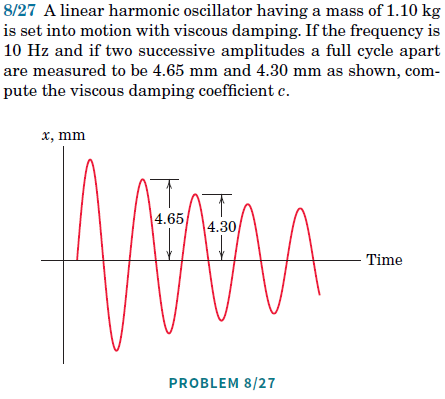

- benyt metode på side 267,

(8/29), 8/33 ,8/35

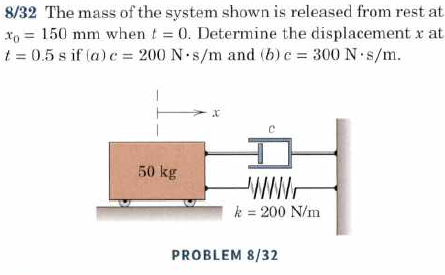

clear all
x_0 = 0.150

x_0 = 0.1500

v_0 = 0

v_0 = 0

t_0 = 0

t_0 = 0

t_1 = 0.5

t_1 = 0.5000

c = 200

c = 200

k = 200

k = 200

m = 50

m = 50


w_n = sqrt(k/m) %egensvingningen

w_n = 2



syms A_1 A_2 t 
zeta = c/(2 * m * w_n) % viscous damping factor or damping ratio

zeta = 1



x = (A_1 + A_2 * t) * exp(-w_n * t)

$$x = {\mathrm{e}}^{-2\,t}\,\left(A_{1}+A_{2}\,t\right)$$

v = diff(x, t)

$$v = A_{2}\,{\mathrm{e}}^{-2\,t}-2\,{\mathrm{e}}^{-2\,t}\,\left(A_{1}+A_{2}\,t\right)$$


[sol_A_1, sol_A_2] = solve([x == x_0, v == v_0], [A_1, A_2]);
A_1 = subs(sol_A_1, t, t_0)

$$A\_1 = \frac{3}{20}$$

A_2 = subs(sol_A_2, t, t_0)

$$A\_2 = \frac{3}{10}$$

x(t) = (A_1 + A_2 * t) * exp(-w_n * t);
v(t) = diff(x(t), t)

$$v(t) = \frac{3\,{\mathrm{e}}^{-2\,t}}{10}-2\,{\mathrm{e}}^{-2\,t}\,\left(\frac{3\,t}{10}+\frac{3}{20}\right)$$


t_max_eq = 0 == v(t);
t_max = solve(t_max_eq, t)

$$t\_max = 0$$

x_max = vpa(x(t_max), 5)

$$x\_max = 0.15$$


x_max = vpa(x(t_1), 5)

$$x\_max = 0.11036$$




syms A1 A2 t x_1
c = 300

c = 300

zeta = c/(2 * m * w_n) % viscous damping factor or damping ratio

zeta = 1.5000



% Ligning 8/10 fra bogen benyttes og sættes lig startpositionen
x_plac_t0 = A1*exp((-zeta + sqrt(zeta^2 - 1))*w_n*t) + A2*exp((-zeta-sqrt(zeta^2-1))*w_n*t) == x_0

$$x\_plac\_t0 = A_{2}\,{\mathrm{e}}^{-\frac{1473822112022165\,t}{281474976710656}}+A_{1}\,{\mathrm{e}}^{-\frac{215027748241771\,t}{281474976710656}}=\frac{3}{20}$$

x_plac_t1 = A1*exp((-zeta + sqrt(zeta^2 - 1))*w_n*t) + A2*exp((-zeta-sqrt(zeta^2-1))*w_n*t) == x_1;

% Hastigheden kommer fra at differentiere placeringsfunktionen, og sætte
% den lig starthastigheden
x_vel = diff(lhs(x_plac_t0), t) == v_0

$$x\_vel = -\frac{1473822112022165\,A_{2}\,{\mathrm{e}}^{-\frac{1473822112022165\,t}{281474976710656}}}{281474976710656}-\frac{215027748241771\,A_{1}\,{\mathrm{e}}^{-\frac{215027748241771\,t}{281474976710656}}}{281474976710656}=0$$


% Ligningerne og de ukendte løses
eqs = [x_plac_t0, x_vel];
vars = [A1, A2];

sols = solve(eqs, vars)

sols = struct with fields:
    A1: (884293267213299*exp((215027748241771*t)/281474976710656))/5035177455121576
    A2: -(645083244725313*exp((1473822112022165*t)/281474976710656))/25175887275607880



% Konstanterne A1 og A2 udregnes, og sættes ind i diff ligningerne til
% tiden t0

A1_ny = vpa(subs(sols.A1, t, t_0),4)

$$A1\_ny = 0.1756$$

A2_ny = vpa(subs(sols.A2, t, t_0),4)

$$A2\_ny = -0.02562$$


% Funktionen præsenteres
funktion = vpa(subs(lhs(x_plac_t1), [A1, A2], [A1_ny, A2_ny]),4)

$$funktion = 0.1756\,{\mathrm{e}}^{-0.7639\,t}-0.02562\,{\mathrm{e}}^{-5.236\,t}$$

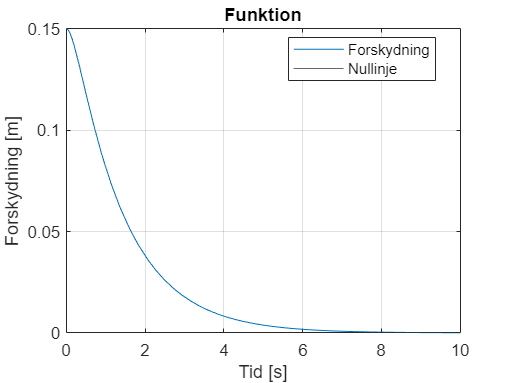

syms func(t)
% xp = x_0;

func(t) = A1_ny*exp((-zeta + sqrt(zeta^2 - 1))*w_n*t) + A2_ny*exp((-zeta-sqrt(zeta^2-1))*w_n*t);

fplot(func(t), [t_0,10], "DisplayName", "Forskydning"), xlabel("Tid [s]"), ylabel("Forskydning [m]"), grid()
yline(t_0, "DisplayName", "Nullinje")

title("Funktion");

legend("Location","best")


vpa(func(0.5), 5)

$$ans = 0.118$$

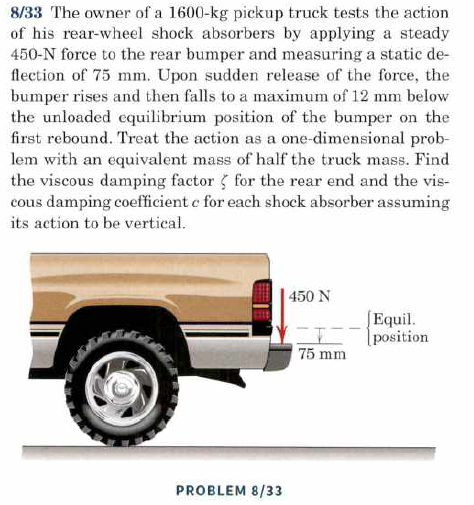

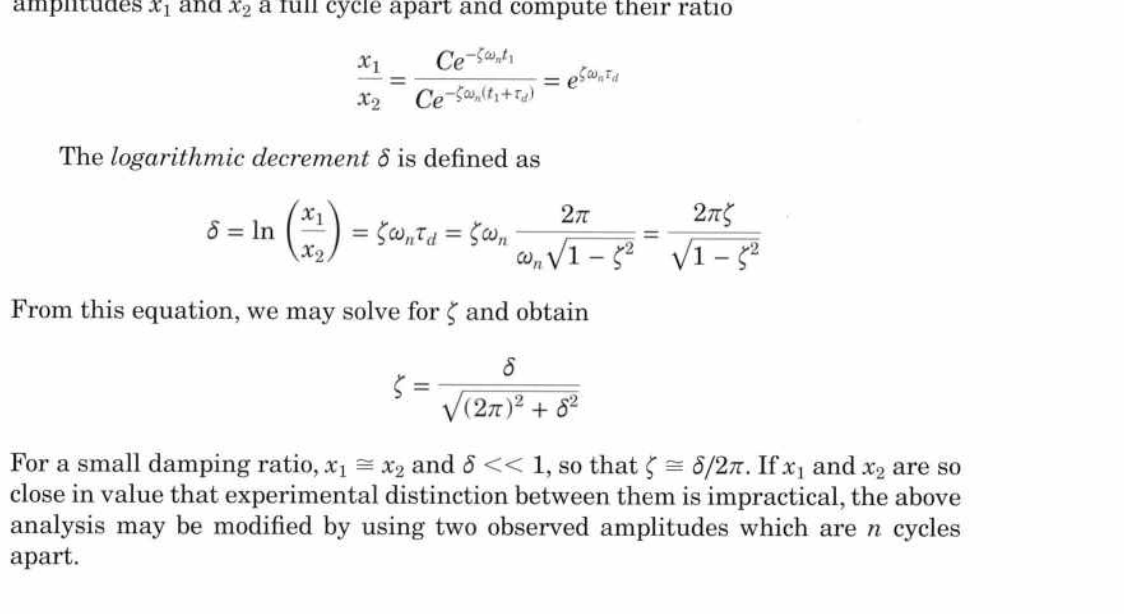

clear all
m = 1600 / 2

m = 800

F = 450

F = 450

x_1 = 0.075

x_1 = 0.0750

x_2 = 0.012

x_2 = 0.0120


delta = log(x_1/x_2)

delta = 1.8326


zeta = delta / sqrt((2*pi)^2 + delta^2)

zeta = 0.2800


k = F/x_1

k = 6000


wn = sqrt(k/m)

wn = 2.7386


syms c
eq_c = zeta == c/(2*m*wn)

$$eq\_c = \frac{315249714612045}{1125899906842624}=\frac{137438953472\,c}{602227320772139}$$

sol = solve(eq_c, c)

$$sol = \frac{189851991004993299460229814255}{154742504910672534362390528}$$

c = vpa(sol,5) / 2

$$c = 613.44486802315805107355117797852$$

# Tvungne svigninger

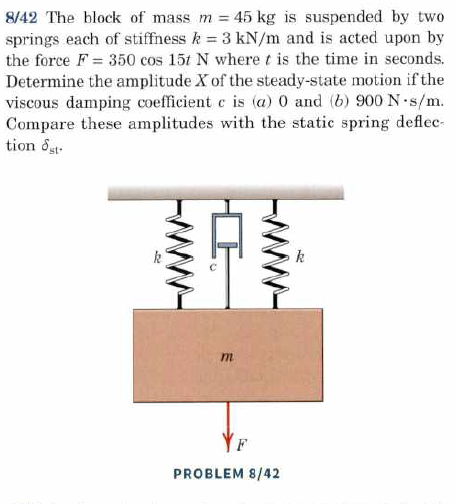

clear all
m = 45;
k = 3000 * 2;
syms A1 A2 t x_1
F(t) = 350 * cos(15*t);

c = 0;

omega_n = sqrt(k/m) %egensvingningen

omega_n = 11.5470


zeta = c/(2*m*omega_n )

zeta = 0


omega = 15; % tvungen svignings frekvens


disp('Aplituden findes')

Aplituden findes


X = (F(0) / k) / sqrt( (1 - (omega / omega_n)^2 )^2 + (2 * zeta * omega / omega_n)^2 )

$$X = \frac{14}{165}$$


vpa(X,5)

$$ans = 0.084848$$


disp('Phase vinklen findes')

Phase vinklen findes


phi = atan((2 * zeta * omega / omega_n)/ (1 - (omega/omega_n)^2 ))

phi = 0


disp('Forskydningen findes nu med ligning 8/22 til') 

Forskydningen findes nu med ligning 8/22 til


x_p = X * sin(omega * t - phi);
x_p_ = vpa(x_p, 3)

$$x\_p\_ = 0.0848\,\sin\left(15.0\,t\right)$$


disp('Vi finder den afledet af forskydningsligninen så vi kan findes dæmperens bidrag')

Vi finder den afledet af forskydningsligninen så vi kan findes dæmperens bidrag


x_p_1 = diff(x_p, t)

$$x\_p\_1 = \frac{14\,\cos\left(15\,t\right)}{11}$$


disp('Kraften overført til gulvet er summen af fjeder og dæmper')

Kraften overført til gulvet er summen af fjeder og dæmper


F_tr = k*x_p + c*x_p_1;
F_tr_ = vpa(F_tr, 3)

$$F\_tr\_ = 509.0\,\sin\left(15.0\,t\right)$$


disp('Den maximale kraft findes hvor sin ledet er 1')

Den maximale kraft findes hvor sin ledet er 1


F_tr_max = X * sqrt(k^2 + c^2 * omega^2);
F_tr_max_ = vpa(F_tr_max, 3)

$$F\_tr\_max\_ = 509.0$$


F_tr_max_final = 271.0

F_tr_max_final = 271

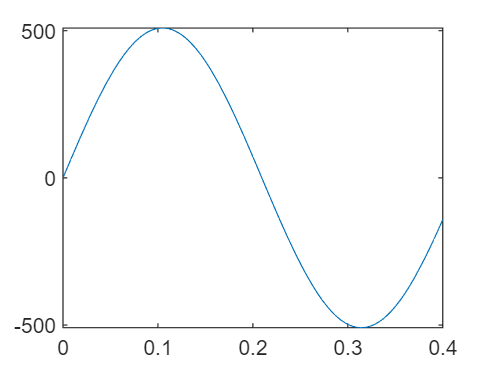


fplot(F_tr, [0,0.4])

clear all
m = 45;
k = 3000 * 2;
syms A1 A2 t x_1
g = 9.81;
F(t) = 350 * cos(15*t);



omega_n = sqrt(k/m) %egensvingningen

omega_n = 11.5470


omega = 15; % tvungen svignings frekvens

c = 900;

zeta = c/(2*m*omega_n)

zeta = 0.8660


F(0)

$$ans = 350$$


disp('Aplituden findes')

Aplituden findes


X = (F(0) / k) / sqrt( (1 - (omega / omega_n)^2 )^2 + (2 * zeta * omega / omega_n)^2 )

$$X = \frac{14\,\sqrt{1417}}{21255}$$


vpa(X,5)

$$ans = 0.024794$$


F_G = m * g

F_G = 441.4500



delta_st = F_G / k %F(0)/k

delta_st = 0.0736


$$\delta_{st} = \frac{F_0}{k}$$


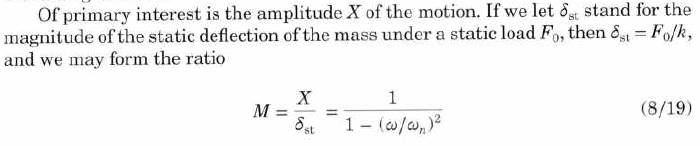


disp('Phase vinklen findes')

Phase vinklen findes


phi = atan((2 * zeta * omega / omega_n)/ (1 - (omega/omega_n)^2 ))

phi = -1.2743


disp('Forskydningen findes nu med ligning 8/22 til') 

Forskydningen findes nu med ligning 8/22 til


x_p = X * sin(omega * t - phi);
x_p_ = vpa(x_p, 3)

$$x\_p\_ = 0.0248\,\sin\left(15.0\,t+1.27\right)$$


disp('Vi finder den afledet af forskydningsligninen så vi kan findes dæmperens bidrag')

Vi finder den afledet af forskydningsligninen så vi kan findes dæmperens bidrag


x_p_1 = diff(x_p, t)

$$x\_p\_1 = \frac{14\,\sqrt{1417}\,\cos\left(15\,t+\frac{358669634800241}{281474976710656}\right)}{1417}$$


disp('Kraften overført til gulvet er summen af fjeder og dæmper')

Kraften overført til gulvet er summen af fjeder og dæmper


F_tr = k*x_p + c*x_p_1;
F_tr_ = vpa(F_tr, 3)

$$F\_tr\_ = 335.0\,\cos\left(15.0\,t+1.27\right)+149.0\,\sin\left(15.0\,t+1.27\right)$$


disp('Den maximale kraft findes hvor sin ledet er 1')

Den maximale kraft findes hvor sin ledet er 1


F_tr_max = X * sqrt(k^2 + c^2 * omega^2);
F_tr_max_ = vpa(F_tr_max, 3)

$$F\_tr\_max\_ = 366.0$$


F_tr_max_final = 271.0

F_tr_max_final = 271

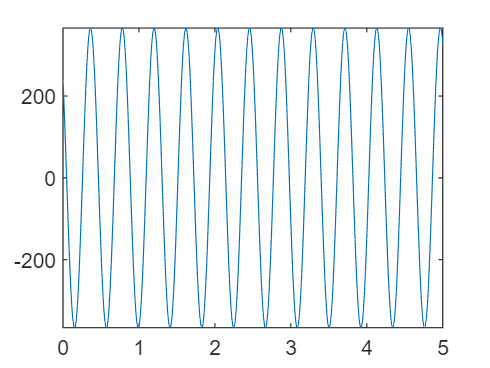


fplot(F_tr, [0,5])

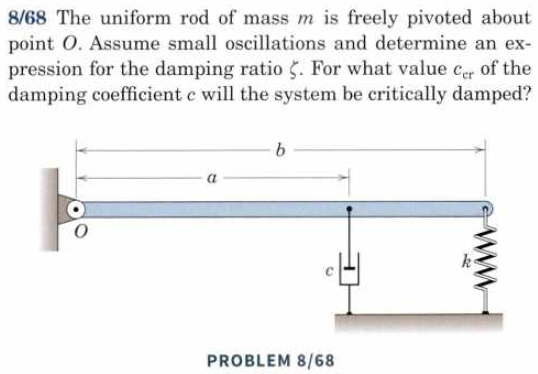

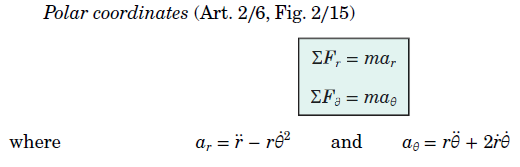

clear all
syms m k c a b
zeta = 1

zeta = 1



eq_M = I * alpha == F_k * b - F_c * a

w_n = sqrt(k/m)

$$w\_n = \sqrt{\frac{k}{m}}$$


eq = zeta == c/(2 * m * w_n)

$$eq = 1=\frac{c}{2\,m\,\sqrt{\frac{k}{m}}}$$


sol = solve(eq, c)

$$sol = 2\,m\,\sqrt{\frac{k}{m}}$$

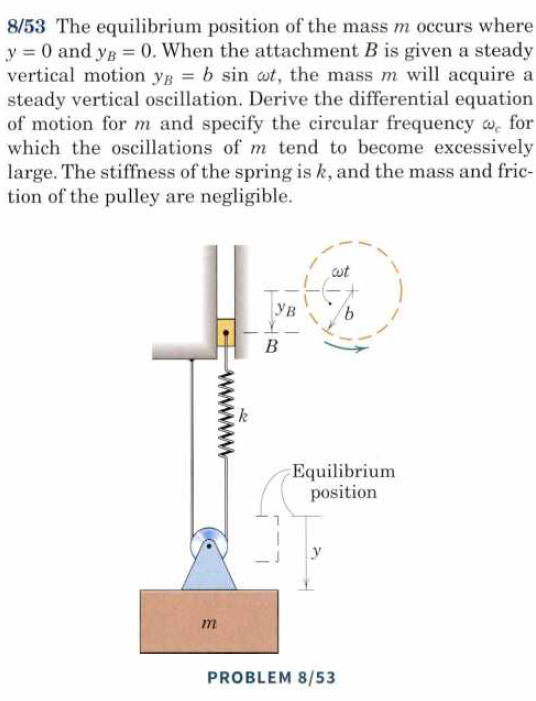

syms m b omega t
y_0 = 0;
y_B_0 = 0;

y_B = b * sin(omega * t)
